# First Slice HDF5 -> bin -> MTEX

**Use code as base for future datasets, its separated in sections to be run more smoothly and with a more easily understandeable structure**

#### Max Solis 02/07/2024

# Z slices

#### Sectioning

plotx2east
% Inputs
nRow = 1531;
nCol = 1301;
height = 1531;  
width = 1301;  
start_row = 1;  
start_col = 1;  

Vtemp = (1:(nRow*nCol)).';
Mtemp = reshape(Vtemp,nRow, nCol);
IDX = Mtemp(start_row:start_row+height-1, start_col:start_col+width-1);
IDXsec = IDX(:)

IDXsec =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


### IDs and pores

poreID = fopen('PhaseID_pore_2M.bin');
A = fread(poreID);
pores_2M = ismember(A, 0);
find(pores_2M)

ans =         9205
       10736
       12266
       13796
       13797
       15326
       15327
       15328
       16856
       16857


### Grain IDs

flabels = fopen('labels_2M.bin');
D = fread(flabels,'int');
labeltemp = reshape(D, [], 1301);
labels = ismember(D, 0);
find(labels);

### Rotations

feuler = fopen('eulers_2M.bin');
ROtemp = fread(feuler,inf,'float','l');
ROT = reshape(ROtemp, 3, []).';
rot = rotation.byEuler(ROT);
% feuler = fopen('quat_2M.bin');
% ROtemp = fread(feuler,inf,'float','l');
% ROT = reshape(ROtemp, 4, []);
% quat = quaternion(ROT);
% rot = rotation(quat);

### Properties

fbse = fopen('BSE_2M.bin');
bsetemp = fread(fbse,inf,'float','l');
fci = fopen('CI_2M.bin');
citemp = fread(fci,inf,'float','l');
ffit = fopen('Fit_2M.bin');
fittemp = fread(ffit,inf,'float','l');
fiq = fopen('IQ_2M.bin');
iqtemp = fread(fiq,inf,'float','l');

prop.ci = citemp(IDXsec);
prop.grainid = D(IDXsec);
prop.iq = iqtemp(IDXsec);
prop.bse = bsetemp(IDXsec);
xlin = 0:0.75:1147.5;
xtemp = repmat(xlin,1,1301).';
ylin = 0:0.75:975;
ytemp = repelem(ylin, 1531).';
prop.x = xtemp(IDXsec);
prop.y = ytemp(IDXsec);
prop.mad = fittemp(IDXsec);
mtexdata martensite;

 
ebsd = EBSD
 
 Phase  Orientations         Mineral         Color  Symmetry  Crystal reference frame
     0   92415 (27%)      notIndexed                                                 
     1  251187 (73%)  Iron bcc (old)  LightSkyBlue       432                         
 
 Properties: bands, bc, bs, error, mad, reliabilityindex, x, y
 Scan unit : um
 cprInfo: show struct
 


CSfcc = ebsd.CSList{1,3};
CSList = {'Pore',CSfcc};

### EBSD

ebsdsec = EBSD(rot(IDXsec),A(IDXsec),CSList,prop)

 
ebsdsec = EBSD
 
 Phase    Orientations   Mineral         Color  Symmetry  Crystal reference frame
     0    2288 (0.11%)      Pore                                                 
     1  1989543 (100%)  Iron fcc  DarkSeaGreen       432                         
 
 Properties: ci, grainid, iq, bse, x, y, mad
 Scan unit : um
 


ebsdsec.orientations = orientation.byEuler(ROT(IDXsec, 1:3));
% ebsdsec.orientations = orientation.byEuler(rot.phi1(IDXsec),rot.Phi(IDXsec),rot.phi2(IDXsec));
ori = ebsdsec.orientations;
odf = calcDensity(ori);

### Plots

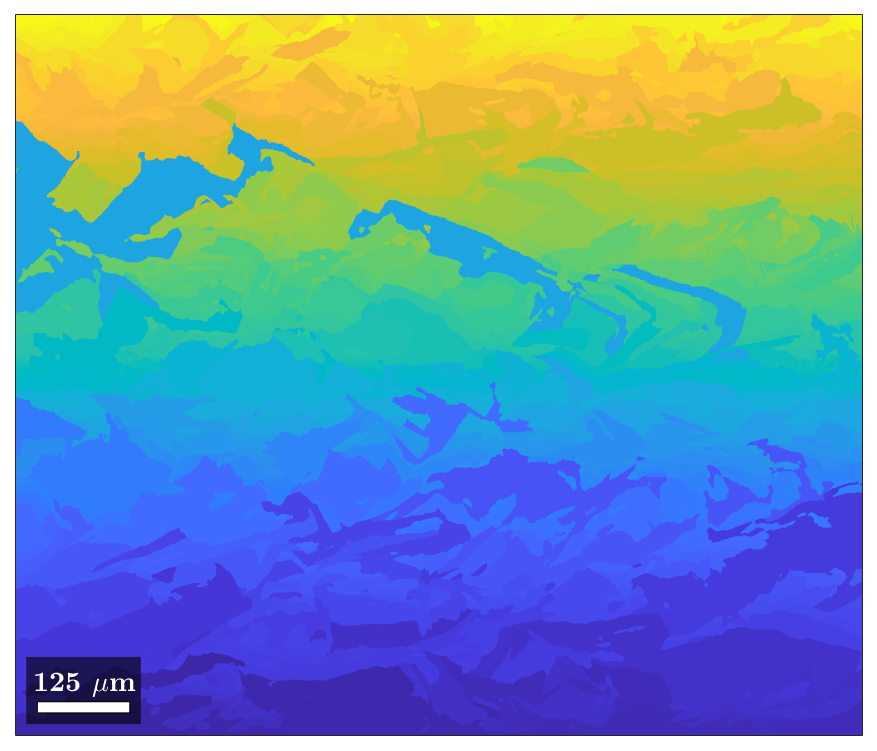

figure()
plot(ebsdsec, ebsdsec.prop.grainid)

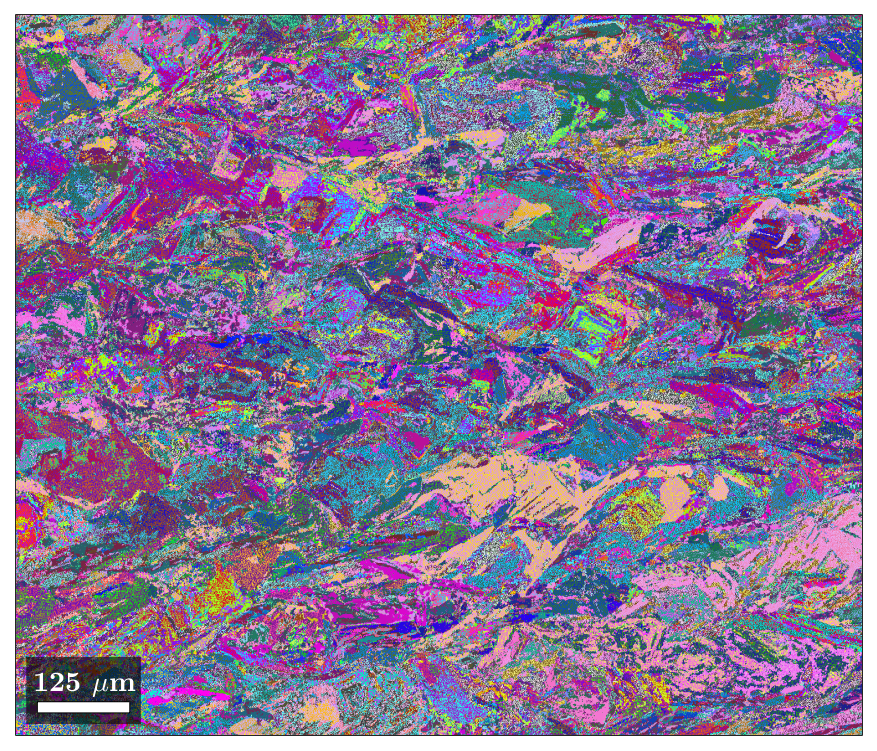

  I'm going to colorize the orientation data with the 
  standard MTEX ipf colorkey. To view the colorkey do:
 
  ipfKey = ipfColorKey(ori_variable_name)
  plot(ipfKey)


% 
figure()
plot(ebsdsec, ebsdsec.orientations)

% ipfKey = ipfColorKey(ebsdsec.orientations)

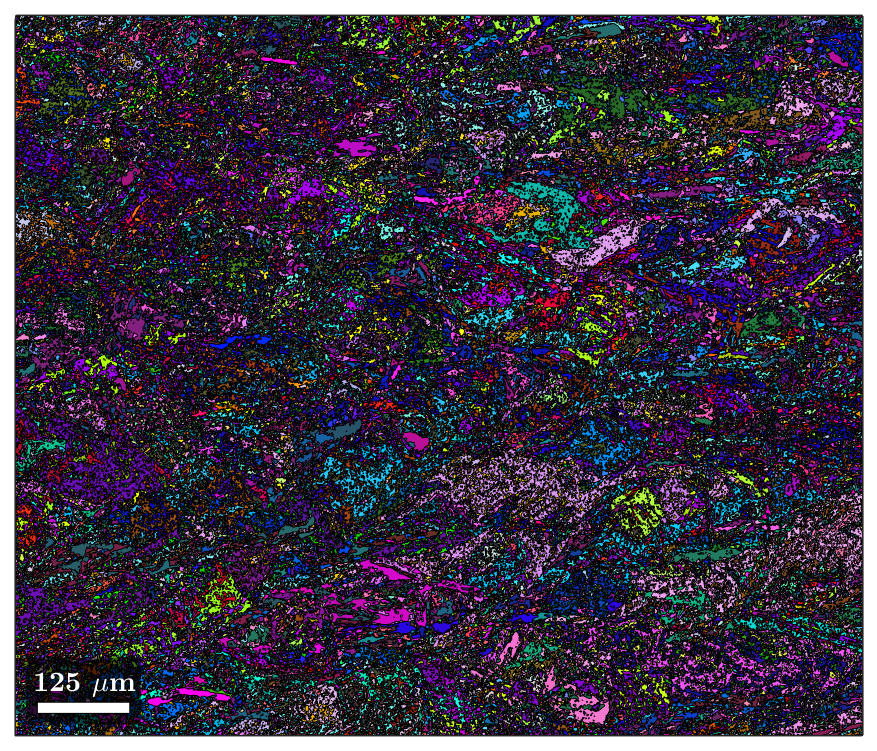

ipfKey = ipfHSVKey(ebsdsec('indexed'));
[grains,ebsdsec.grainId] = calcGrains(ebsdsec('indexed'),'angle',15*degree);
ebsdsec(grains(grains.grainSize < 3)) = [];
[grains,ebsdsec.grainId] = calcGrains(ebsdsec('indexed'),'angle',15*degree);
grains = smooth(grains,5);
colors = ipfKey.orientation2color(grains.meanOrientation);
figure()
plot(grains, colors)

% figure()
% ipfKey.colorPostRotation = reflection(yvector);
% plot(ipfKey)

% [grains, ebsdsec.grainId] = calcGrains(ebsdsec('indexed'));
% ebsdsec(grains(grains.grainSize < 5)) = [];
% [grains, ebsdsec.grainId] = calcGrains(ebsdsec('indexed'),'threshold',80*degree);
% ebsdsec = ebsdsec.project2FundamentalRegion;
% grains = smooth(grains,5);
% plot(ebsdsec, ebsdsec.orientations)
% hold on
% plot(grains.boundary,'lineWidth',2)
% hold off

% hold on
% [grains,ebsdsec.grainid] = calcGrains(ebsdsec);
% grains(grains.grainSize < 10) = [];
% plot(grains.boundary,'color','k','linewidth',1.5)
% hold off
% 
% [grains,ebsdsec.grainId] = calcGrains(ebsdsec,'angle',5*degree);
% ipfKey = ipfHSVKey(ebsdsec);
% colors = ipfKey.orientation2color(ebsdsec.orientations);
% ipfKey.colorPostRotation = reflection(yvector);
% % plot the ebsd data together with the colors
% figure()
% plot(ebsdsec,colors)
% 
% figure()
% plot(ipfKey)
% % plot(grains.boundary,'lineWidth',1.5,'micronbar','off')

% figure()
% plot(ipfKey)
% % figure()
% % plot(odf)

% big_grains = grains(grains.grainSize>10);
% % plot them
% plot(big_grains,big_grains.meanOrientation,'micronbar','off')
% 
% % plot on top their ids
% text(big_grains,int2str(big_grains.id))
% % plot(ipfKey,'3d')


Symmetry checks

% mtexdata martensite
% cs = ebsd.CSList{1,3}
% ss = specimenSymmetry('432')
% oriT = orientation.byEuler(126.6*degree,71*degree,312.6*degree)
% grains(3918).CS.color = []
% oriT = ori(3918)
% eq1 = oriT * cs


id = ebsdsec.prop.grainid

id =      1
     1
     1
     1
     1
     2
     2
     2
     2
     2


[a,b]=hist(id,unique(id));
sizes = [b,a.']

sizes =            1          57
           2       18173
           3        2961
           4        1042
           5         112
           6         184
           7         398
           8         113
           9        1645
          10         152


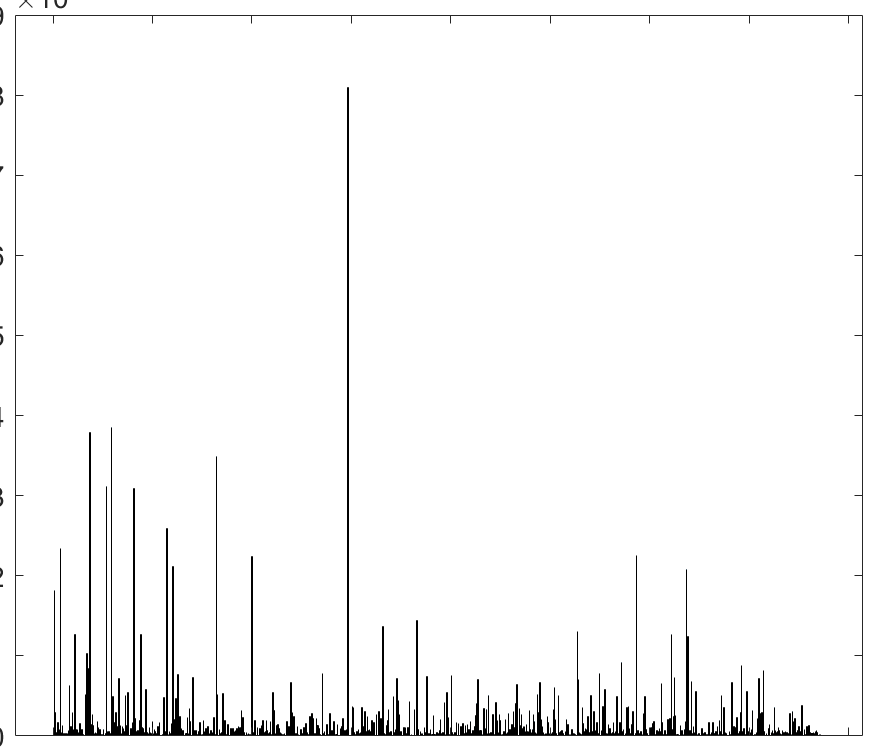

histogram(id,unique(id))

[B,I] = maxk(sizes,20);
sizIDX = [I(:,2),B(:,2)]

sizIDX =          584       80892
         115       38564
          72       37876
         322       34929
         105       31188
         159       30862
         225       25940
          14       23365
        1161       22527
         393       22433
